# `Involute Curve Generator for Spur Gears:`

k=10 %% Specify Gear Module in millimeters

k = 10

p=20 %% Specify pressure angle of the gear in degrees

p = 20

n=30 %% Specify number of tooth on gear. If pitch diameter(d) is given then n=d/m

n = 30

cp=pi*k

cp = 31.4159

## Calculation of the basic parameters:

- base circle radius: rb

- addendum circle radius: ra

- pitch circle radius: rp

rp=(k*n)/2

rp = 150

rb=rp*cosd(p)

rb = 140.9539

ra=rp+k

ra = 160

## Calculation of Gamma Angles in radians:

Multiply with (180/pi) for conversion to degrees

ga=((((ra/rb)^2)-1)^0.5) %% Gamma for addendum circle radius

ga = 0.5371

gp=((((rp/rb)^2)-1)^0.5) %% Gamma for pitch circle radius

gp = 0.3640

z=5 %% Specify Number of Shi values needed

z = 5

gm=0:0.001:ga %% Creating a range of gamma values for plotting lower side of involute tooth

gm =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


## Calculation of theta angles in radians:

ta=ga-atan(ga) %% Theta for addendum circle radius

ta = 0.0442

tp=gp-atan(gp) %% Theta for pitch circle radius

tp = 0.0149

ty=gm-atan(gm) %% Corresponding range of Theta values for plotting lower side of involute tooth

ty =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


## Calculation of Shi angles in radians:

sa=tp+(pi/(2*n))-ta %% Shi for addendum circle radius

sa = 0.0230

sans=tp+(pi/(2*n))-gm %% Corresponding range of Shi values for plotting lower side of involute tooth

sans =     0.0673    0.0663    0.0653    0.0643    0.0633    0.0623    0.0613    0.0603    0.0593    0.0583    0.0573    0.0563    0.0553    0.0543    0.0533    0.0523    0.0513    0.0503    0.0493    0.0483    0.0473    0.0463    0.0453    0.0443    0.0433    0.0423    0.0413    0.0403    0.0393    0.0383    0.0373    0.0363    0.0353    0.0343    0.0333    0.0323    0.0313    0.0303    0.0293    0.0283    0.0273    0.0263    0.0253    0.0243    0.0233    0.0223    0.0213    0.0203    0.0193    0.0183


sm=ta:0.001:ta+(2*sa)

sm =     0.0442    0.0452    0.0462    0.0472    0.0482    0.0492    0.0502    0.0512    0.0522    0.0532    0.0542    0.0552    0.0562    0.0572    0.0582    0.0592    0.0602    0.0612    0.0622    0.0632    0.0642    0.0652    0.0662    0.0672    0.0682    0.0692    0.0702    0.0712    0.0722    0.0732    0.0742    0.0752    0.0762    0.0772    0.0782    0.0792    0.0802    0.0812    0.0822    0.0832    0.0842    0.0852    0.0862    0.0872    0.0882    0.0892    0.0902


g=size(sm)

g =      1    47


## Calculation of Corresponding radii from gear centre:

ry=rb*((1+(gm.^2)).^0.5) %% Corresponding range of radii values for plotting lower side of involute tooth

ry =   140.9539  140.9540  140.9542  140.9545  140.9550  140.9557  140.9564  140.9573  140.9584  140.9596  140.9609  140.9624  140.9640  140.9658  140.9677  140.9697  140.9719  140.9743  140.9767  140.9793  140.9821  140.9850  140.9880  140.9912  140.9945  140.9979  141.0015  141.0053  141.0091  141.0132  141.0173  141.0216  141.0260  141.0306  141.0353  141.0402  141.0452  141.0503  141.0556  141.0610  141.0666  141.0723  141.0782  141.0841  141.0903  141.0965  141.1029  141.1095  141.1162  141.1230


ty2=ty+(2*sa)+ta %% Range of Theta angles for other side of involute tooth

ty2 =     0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903    0.0903


gm2=flip(gm)

gm2 =     0.5370    0.5360    0.5350    0.5340    0.5330    0.5320    0.5310    0.5300    0.5290    0.5280    0.5270    0.5260    0.5250    0.5240    0.5230    0.5220    0.5210    0.5200    0.5190    0.5180    0.5170    0.5160    0.5150    0.5140    0.5130    0.5120    0.5110    0.5100    0.5090    0.5080    0.5070    0.5060    0.5050    0.5040    0.5030    0.5020    0.5010    0.5000    0.4990    0.4980    0.4970    0.4960    0.4950    0.4940    0.4930    0.4920    0.4910    0.4900    0.4890    0.4880


ry2=rb*((1+(gm2.^2)).^0.5) %% Range of radii for other side of involute tooth

ry2 =   159.9916  159.9250  159.8584  159.7920  159.7256  159.6594  159.5932  159.5272  159.4612  159.3954  159.3296  159.2639  159.1984  159.1329  159.0675  159.0022  158.9371  158.8720  158.8070  158.7421  158.6773  158.6127  158.5481  158.4836  158.4192  158.3549  158.2907  158.2266  158.1626  158.0988  158.0350  157.9713  157.9077  157.8442  157.7808  157.7175  157.6543  157.5912  157.5283  157.4654  157.4026  157.3399  157.2773  157.2148  157.1525  157.0902  157.0280  156.9659  156.9040  156.8421


## Calculation of Corresponding Parameters for other side of the involute tooth:

gm3=-ga:0.001:0  %% Range of gamma for other side of involute tooth

gm3 =    -0.5371   -0.5361   -0.5351   -0.5341   -0.5331   -0.5321   -0.5311   -0.5301   -0.5291   -0.5281   -0.5271   -0.5261   -0.5251   -0.5241   -0.5231   -0.5221   -0.5211   -0.5201   -0.5191   -0.5181   -0.5171   -0.5161   -0.5151   -0.5141   -0.5131   -0.5121   -0.5111   -0.5101   -0.5091   -0.5081   -0.5071   -0.5061   -0.5051   -0.5041   -0.5031   -0.5021   -0.5011   -0.5001   -0.4991   -0.4981   -0.4971   -0.4961   -0.4951   -0.4941   -0.4931   -0.4921   -0.4911   -0.4901   -0.4891   -0.4881


ry3=rb*((1+(gm3.^2)).^0.5) %% Range of radii for other side of involute tooth

ry3 =   160.0000  159.9334  159.8668  159.8003  159.7340  159.6677  159.6016  159.5355  159.4695  159.4036  159.3379  159.2722  159.2066  159.1411  159.0757  159.0104  158.9453  158.8802  158.8152  158.7503  158.6855  158.6208  158.5562  158.4917  158.4273  158.3630  158.2988  158.2347  158.1707  158.1068  158.0430  157.9793  157.9157  157.8522  157.7888  157.7255  157.6623  157.5992  157.5362  157.4733  157.4105  157.3478  157.2852  157.2227  157.1603  157.0980  157.0358  156.9737  156.9118  156.8499


ty4=gm3-atan(gm3) %% Range of theta for other side of involute tooth

ty4 =    -0.0442   -0.0440   -0.0438   -0.0436   -0.0433   -0.0431   -0.0429   -0.0427   -0.0424   -0.0422   -0.0420   -0.0418   -0.0416   -0.0414   -0.0411   -0.0409   -0.0407   -0.0405   -0.0403   -0.0401   -0.0399   -0.0397   -0.0395   -0.0392   -0.0390   -0.0388   -0.0386   -0.0384   -0.0382   -0.0380   -0.0378   -0.0376   -0.0374   -0.0372   -0.0370   -0.0368   -0.0366   -0.0364   -0.0362   -0.0360   -0.0358   -0.0356   -0.0354   -0.0352   -0.0350   -0.0348   -0.0346   -0.0344   -0.0342   -0.0340


ty5=ty4+(2*sa)+(2*ta) %% Shift the range of theta values by the angle subtended by the rest of the gear tooth at the centre of the gear

ty5 =     0.0903    0.0905    0.0908    0.0910    0.0912    0.0914    0.0916    0.0919    0.0921    0.0923    0.0925    0.0927    0.0929    0.0932    0.0934    0.0936    0.0938    0.0940    0.0942    0.0944    0.0947    0.0949    0.0951    0.0953    0.0955    0.0957    0.0959    0.0961    0.0963    0.0965    0.0967    0.0969    0.0971    0.0973    0.0975    0.0977    0.0980    0.0982    0.0984    0.0985    0.0987    0.0989    0.0991    0.0993    0.0995    0.0997    0.0999    0.1001    0.1003    0.1005


o=ones(1,g(2))

o =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


ras=o.*ra %% Creating array of addendum circle radius for polar plot

ras =    160   160   160   160   160   160   160   160   160   160   160   160   160   160   160   160   160   160   160   160   160   160   160   160   160   160   160   160   160   160   160   160   160   160   160   160   160   160   160   160   160   160   160   160   160   160   160


## Plotting the Tooth:

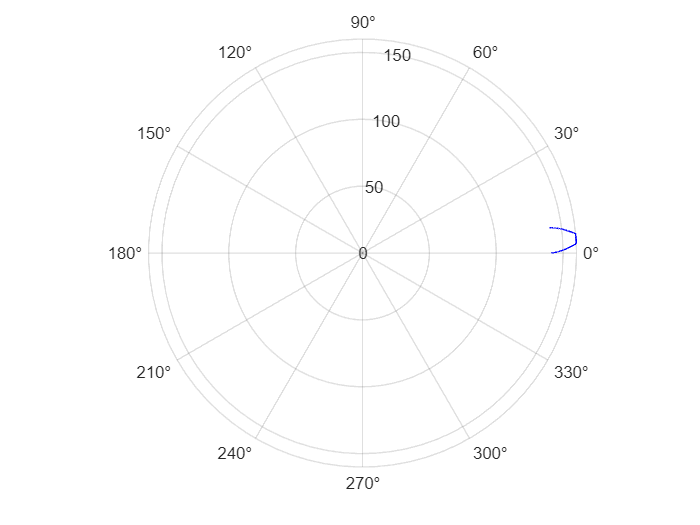

polarplot(ty,ry,'b')
hold on
polarplot(sm,ras,'b')
hold on
polarplot(ty5,ry3,'b')